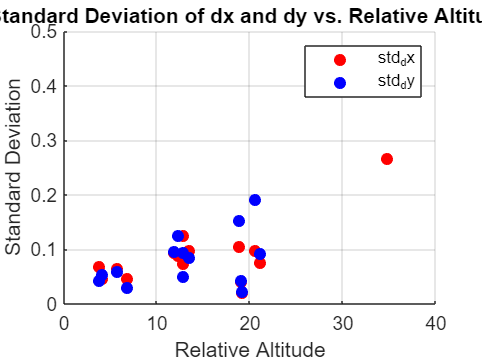

% Clear workspace
clear;
clc;

% Specify the directories
txt_files_directory = '\\sf3.bss.phy.private.cam.ac.uk\cicutagroup\yz655\camera_shake_detection\drone_scale_bar_videos_movement_data';
excel_file = 'C:\Users\46596\Desktop\Multi DDM\DJI_0004_local (version 1).xlsx';

sigma = 2; % Choose the desired standard deviation for the Gaussian filter

% Get the list of .txt files in the directory
txt_files = dir(fullfile(txt_files_directory, 'scalebar_fps10_DJI_*.txt'));

% Read the table from the Excel file
excel_data = readtable(excel_file, 'Range', 'A1:AA1000', 'PreserveVariableNames', true); % Adjust the range as needed

% Initialize the results structure
results = struct('video_number', {}, 'std_dx', {}, 'std_dy', {}, 'relative_altitude', {});

% Iterate through the text files and process the data
for i = 1:length(txt_files)
    % Read the camera_movement_data from the text file
    camera_movement_data = jsondecode(fileread(fullfile(txt_files(i).folder, txt_files(i).name)));

    % Extract the dx_list and dy_list from the camera_movement_data matrix
    dx_list = camera_movement_data(:, 1);
    dy_list = camera_movement_data(:, 2);

    % Apply Gaussian smoothing
    dx_list_smoothed = imgaussfilt(dx_list, sigma);
    dy_list_smoothed = imgaussfilt(dy_list, sigma);

    % Calculate the standard deviation of dx and dy
    std_dx = std(dx_list_smoothed);
    std_dy = std(dy_list_smoothed);

    % Extract the video number from the file name
    video_number = str2double(regexp(txt_files(i).name, '(?<=DJI_00)\d+', 'match', 'once'));

    % Find the corresponding row in the Excel data
    row_idx = find(excel_data.FileName == "DJI_00" + string(video_number) + ".MP4", 1);

    % Get the relative altitude from the Excel data
    relative_altitude = excel_data.RelativeAltitude(row_idx);

    % Store the results
    results(i).video_number = video_number;
    results(i).std_dx = std_dx;
    results(i).std_dy = std_dy;
    results(i).relative_altitude = relative_altitude;
end

% Plot std_dx, std_dy, and relative_altitude
figure;
scatter([results.relative_altitude], [results.std_dx], 'r', 'filled');
hold on;
scatter([results.relative_altitude], [results.std_dy], 'b', 'filled');
xlabel('Relative Altitude');
ylabel('Standard Deviation');
legend('std_dx', 'std_dy');
title('Standard Deviation of dx and dy vs. Relative Altitude');
grid on;
hold off;

% Clear workspace
clear;
clc;

% Specify the directories
txt_files_directory = '\\sf3.bss.phy.private.cam.ac.uk\cicutagroup\yz655\camera_shake_detection\drone_scale_bar_videos_movement_data';
excel_file = 'C:\Users\46596\Desktop\Multi DDM\DJI_0004_local (version 1).xlsx';

% Get the list of .txt files in the directory
txt_files = dir(fullfile(txt_files_directory, 'scalebar_fps10_DJI_*.txt'));

% Read the table from the Excel file
excel_data = readtable(excel_file, 'Range', 'A1:AA1000', 'PreserveVariableNames', true); % Adjust the range as needed

% Initialize the results structure
results = struct('video_number', {}, 'std_dx', {}, 'std_dy', {}, 'relative_altitude', {});

% Iterate through the text files and process the data
for i = 1:length(txt_files)
    % Read the camera_movement_data from the text file
    camera_movement_data = jsondecode(fileread(fullfile(txt_files(i).folder, txt_files(i).name)));

    % Extract dx and dy from camera_movement_data
    dx_list = [camera_movement_data(1:2:end)];
    dy_list = [camera_movement_data(2:2:end)];

    % Calculate the standard deviation of dx and dy
    std_dx = std(dx_list);
    std_dy = std(dy_list);

    % Extract the video number from the file name
    video_number = str2double(regexp(txt_files(i).name, '(?<=DJI_00)\d+', 'match', 'once'));

    % Find the corresponding row in the Excel data
    row_idx = find(excel_data.FileName == "DJI_00" + string(video_number) + ".MP4", 1);

    % Get the relative altitude from the Excel data
    relative_altitude = excel_data.RelativeAltitude(row_idx);

    % Store the results
    results(i).video_number = video_number;
    results(i).std_dx = std_dx;
    results(i).std_dy = std_dy;
    results(i).relative_altitude = relative_altitude;
end

% Plot std_dx, std_dy, and relative_altitude
figure;
scatter([results.relative_altitude], [results.std_dx], 'r', 'filled');
hold on;
scatter([results.relative_altitude], [results.std_dy], 'b', 'filled');
xlabel('Relative Altitude');
ylabel('Standard Deviation');
legend('std_dx', 'std_dy');
title('Standard Deviation of dx and dy vs. Relative Altitude');
grid on;
hold off;

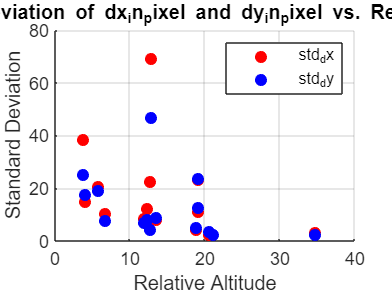

% Clear workspace
clear;
clc;

% Specify the directories
txt_files_directory = '\\sf3.bss.phy.private.cam.ac.uk\cicutagroup\yz655\camera_shake_detection\drone_scale_bar_videos_movement_data';
excel_file = 'C:\Users\46596\Desktop\Multi DDM\DJI_0004_local (version 1).xlsx';

sigma = 2; % Choose the desired standard deviation for the Gaussian filter

% Get the list of .txt files in the directory
txt_files = dir(fullfile(txt_files_directory, 'scalebar_fps10_DJI_*.txt'));

% Read the table from the Excel file
excel_data = readtable(excel_file, 'Range', 'A1:AA1000', 'PreserveVariableNames', true); % Adjust the range as needed

% Initialize the results structure
results = struct('video_number', {}, 'std_dx', {}, 'std_dy', {}, 'relative_altitude', {});

% Iterate through the text files and process the data
for i = 1:length(txt_files)
    % Read the camera_movement_data from the text file
    camera_movement_data = jsondecode(fileread(fullfile(txt_files(i).folder, txt_files(i).name)));

    % Extract the dx_list and dy_list from the camera_movement_data matrix
    dx_list = camera_movement_data(:, 3);
    dy_list = camera_movement_data(:, 4);

    % Apply Gaussian smoothing
    dx_list_smoothed = imgaussfilt(dx_list, sigma);
    dy_list_smoothed = imgaussfilt(dy_list, sigma);

    % Calculate the standard deviation of dx and dy
    std_dx = std(dx_list_smoothed);
    std_dy = std(dy_list_smoothed);

    % Extract the video number from the file name
    video_number = str2double(regexp(txt_files(i).name, '(?<=DJI_00)\d+', 'match', 'once'));

    % Find the corresponding row in the Excel data
    row_idx = find(excel_data.FileName == "DJI_00" + string(video_number) + ".MP4", 1);

    % Get the relative altitude from the Excel data
    relative_altitude = excel_data.RelativeAltitude(row_idx);

    % Store the results
    results(i).video_number = video_number;
    results(i).std_dx = std_dx;
    results(i).std_dy = std_dy;
    results(i).relative_altitude = relative_altitude;
end

% Plot std_dx, std_dy, and relative_altitude
figure;
scatter([results.relative_altitude], [results.std_dx], 'r', 'filled');
hold on;
scatter([results.relative_altitude], [results.std_dy], 'b', 'filled');
xlabel('Relative Altitude');
ylabel('Standard Deviation');
legend('std_dx', 'std_dy');
title('Standard Deviation of dx_in_pixel and dy_in_pixel vs. Relative Altitude');
grid on;
hold off;